# Questuion 4

## Part a

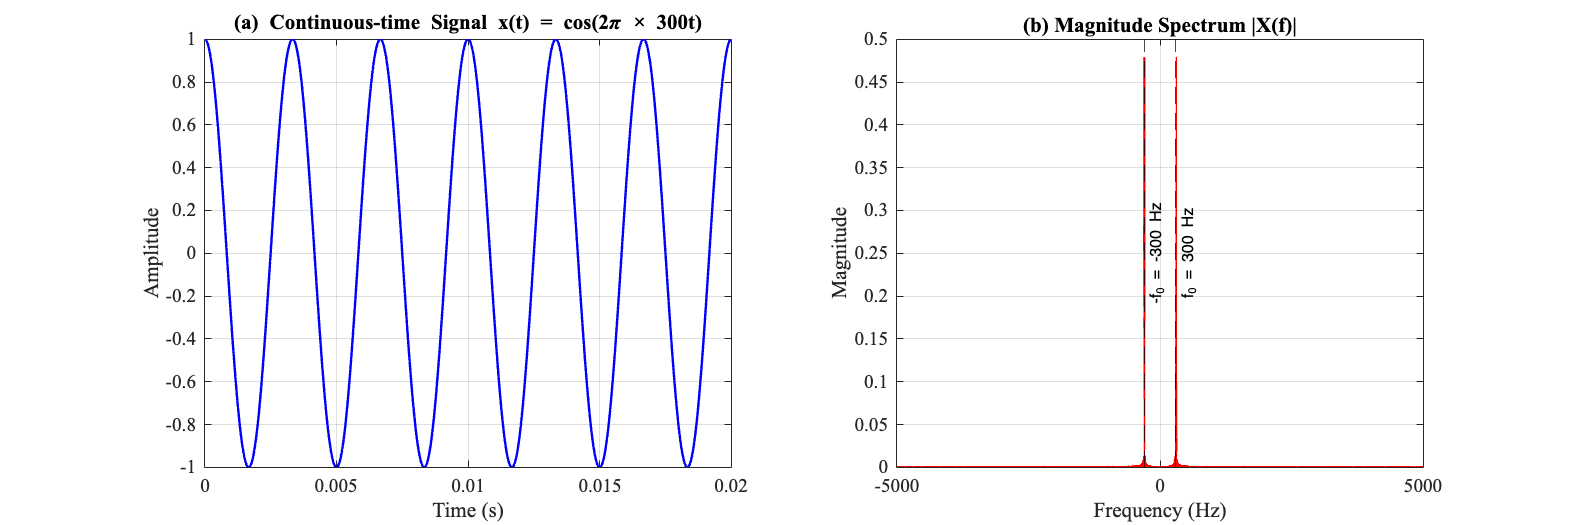

%% (a) The Signal: Create continuous-time signal and plot spectrum

fs_high = 50000;  % High sampling rate to simulate continuous-time
t_continuous = 0:1/fs_high:1;  % 1 second duration
f0 = 300;  % Signal frequency

% Continuous-time signal
x_t = cos(2*pi*f0*t_continuous);

% Compute FFT for frequency analysis
N_fft = 2^nextpow2(length(x_t));
X_f = fft(x_t, N_fft);
f_axis = (-N_fft/2:N_fft/2-1) * (fs_high/N_fft);

% Plot time domain and frequency domain
figure('Position', [100, 100, 1200, 400]);

subplot(1,2,1);
plot(t_continuous(1:1000), x_t(1:1000), 'b', 'LineWidth', 1.5);
title('(a) Continuous-time Signal x(t) = cos(2\pi × 300t)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(1,2,2);
plot(f_axis, fftshift(abs(X_f))/length(x_t), 'r', 'LineWidth', 1.5);
xlim([-5000, 5000]);
title('(b) Magnitude Spectrum |X(f)|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xline(300, 'k--', 'f_0 = 300 Hz', 'LabelVerticalAlignment', 'middle');
xline(-300, 'k--', '-f_0 = -300 Hz', 'LabelVerticalAlignment', 'middle');

## Part b

fs_good = 1000;  % f_s > 2f_0 = 600 Hz (Nyquist satisfied)
downsample_factor_good = fs_high / fs_good;
x1_n = x_t(1:downsample_factor_good:end);  % Sampling by taking every 50th point
t1 = (0:length(x1_n)-1) / fs_good;

% Compute FFT of sampled signal
X1_f = fft(x1_n, N_fft);
f1_axis = (-N_fft/2:N_fft/2-1) * (fs_good/N_fft);

## Part c

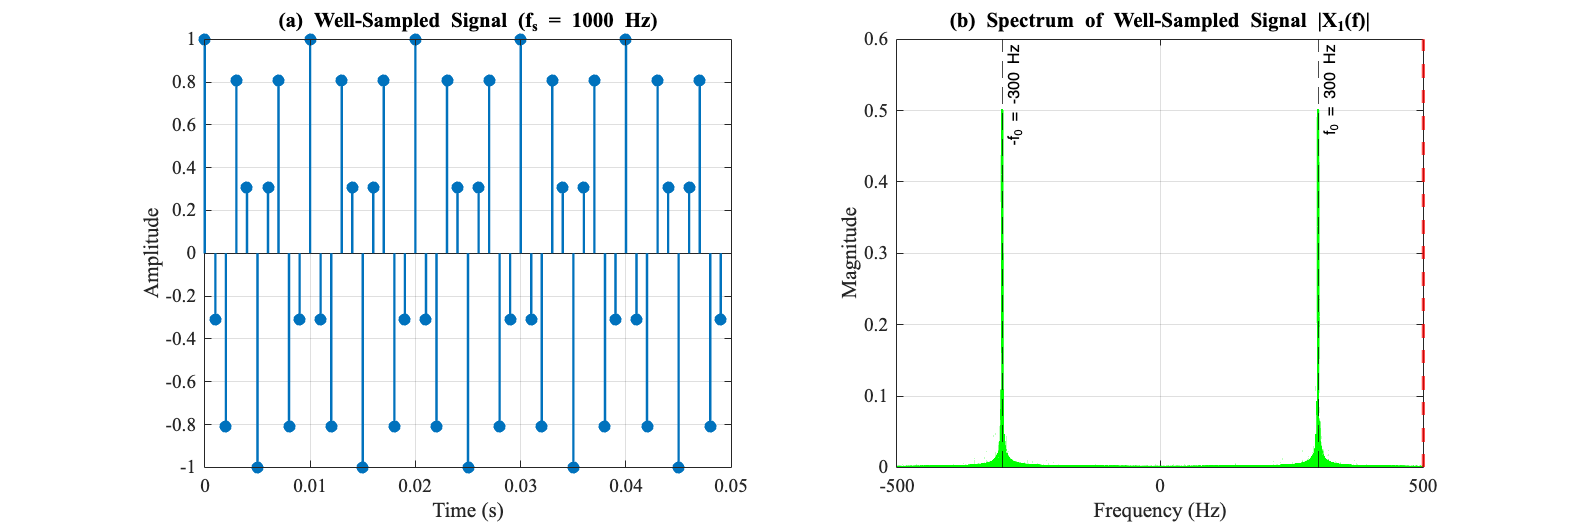

figure('Position', [100, 100, 1200, 400]);

subplot(1,2,1);
stem(t1(1:50), x1_n(1:50), 'filled', 'LineWidth', 1.5);
title('(a) Well-Sampled Signal (f_s = 1000 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(1,2,2);
plot(f1_axis, fftshift(abs(X1_f))/length(x1_n), 'g', 'LineWidth', 1.5);
xlim([-fs_good/2, fs_good/2]);
title('(b) Spectrum of Well-Sampled Signal |X_1(f)|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xline(300, 'k--', 'f_0 = 300 Hz');
xline(-300, 'k--', '-f_0 = -300 Hz');
xline(fs_good/2, 'r--', 'f_s/2 = 500 Hz', 'LineWidth', 2);

## Part D

fs_bad = 400;  % f_s < 2f_0 = 600 Hz (Nyquist violated)
downsample_factor_bad = fs_high / fs_bad;
x2_n = x_t(1:downsample_factor_bad:end);  % Sampling by taking every 125th point
t2 = (0:length(x2_n)-1) / fs_bad;

% Compute FFT of aliased signal
X2_f = fft(x2_n, N_fft);
f2_axis = (-N_fft/2:N_fft/2-1) * (fs_bad/N_fft);


## Part E

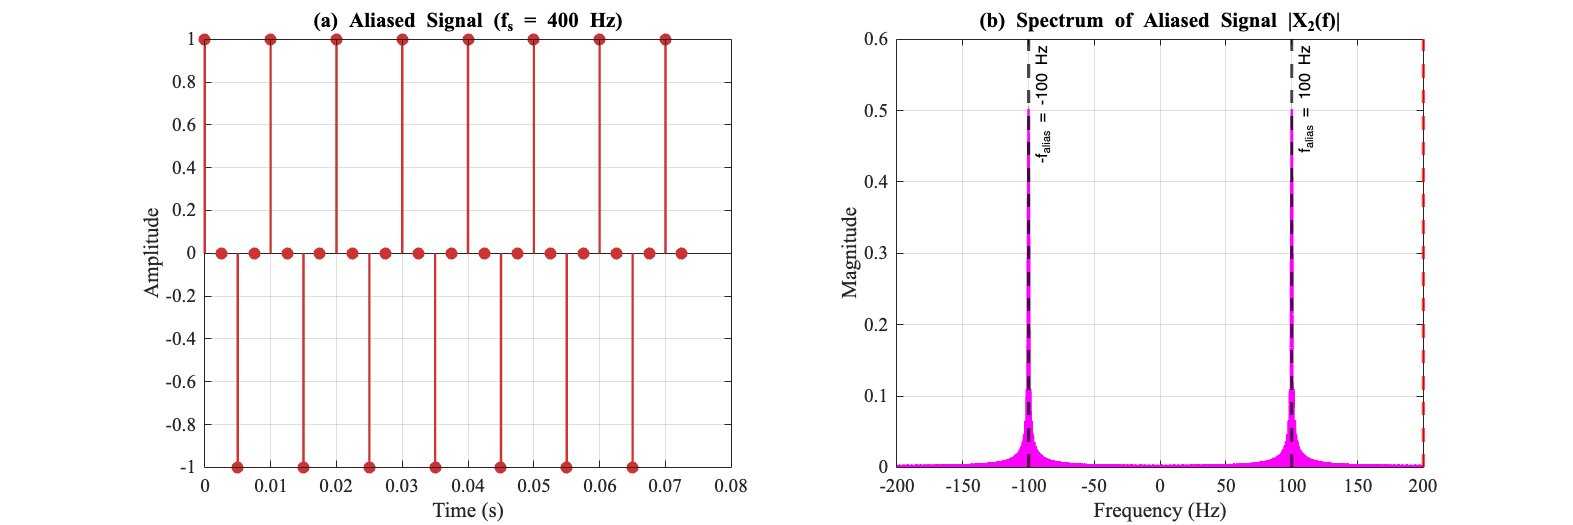

figure('Position', [100, 100, 1200, 400]);

subplot(1,2,1);
stem(t2(1:30), x2_n(1:30), 'filled', 'LineWidth', 1.5, 'Color', [0.8, 0.2, 0.2]);
title('(a) Aliased Signal (f_s = 400 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(1,2,2);
plot(f2_axis, fftshift(abs(X2_f))/length(x2_n), 'm', 'LineWidth', 1.5);
xlim([-fs_bad/2, fs_bad/2]);
title('(b) Spectrum of Aliased Signal |X_2(f)|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Calculate and display aliased frequency
f_alias = abs(f0 - fs_bad);
xline(f_alias, 'k--', sprintf('f_{alias} = %d Hz', f_alias), 'LineWidth', 2);
xline(-f_alias, 'k--', sprintf('-f_{alias} = -%d Hz', f_alias), 'LineWidth', 2);
xline(fs_bad/2, 'r--', 'f_s/2 = 200 Hz', 'LineWidth', 2);

## Part H

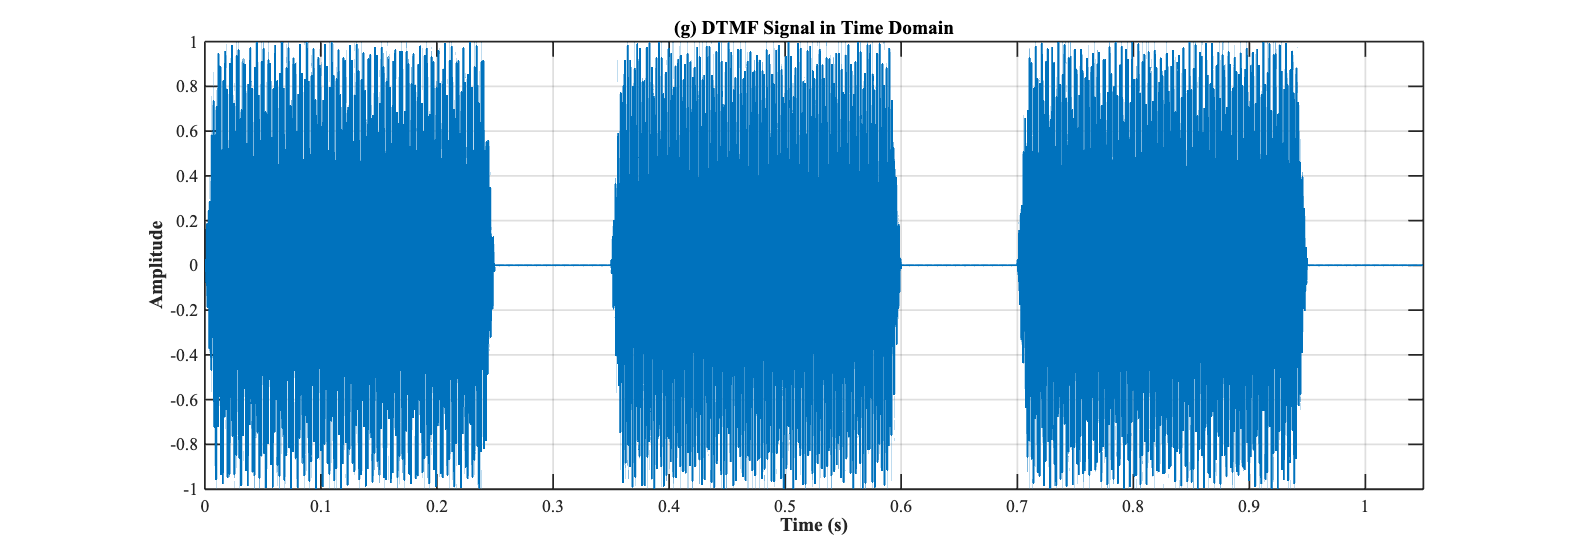

% DTMF Signal Analysis and Decoding
clear; close all; clc;

%% Load DTMF signal
[x, fs] = audioread('dtmf_sequence.wav');
if size(x,2) > 1
    x = mean(x,2); % convert to mono if stereo
end
x = x / max(abs(x)); % normalize amplitude
N = length(x);
t = (0:N-1)/fs;

% DTMF standard frequencies and mapping
low_freqs  = [697, 770, 852, 941];
high_freqs = [1209, 1336, 1477];
dtmf_keys = {'1','2','3'; '4','5','6'; '7','8','9'; '*','0','#'};

% Time-Domain Plot 
figure('Position',[100,100,1000,350],'Color','w');
plot(t, x, 'Color', [0 0.4470 0.7410], 'LineWidth', 1.3);
xlabel('Time (s)','FontSize',12,'FontWeight','bold');
ylabel('Amplitude','FontSize',12,'FontWeight','bold');
title('(g) DTMF Signal in Time Domain','FontSize',14,'FontWeight','bold');
grid on; xlim([0 t(end)]);
set(gca,'FontSize',11,'LineWidth',1.1);

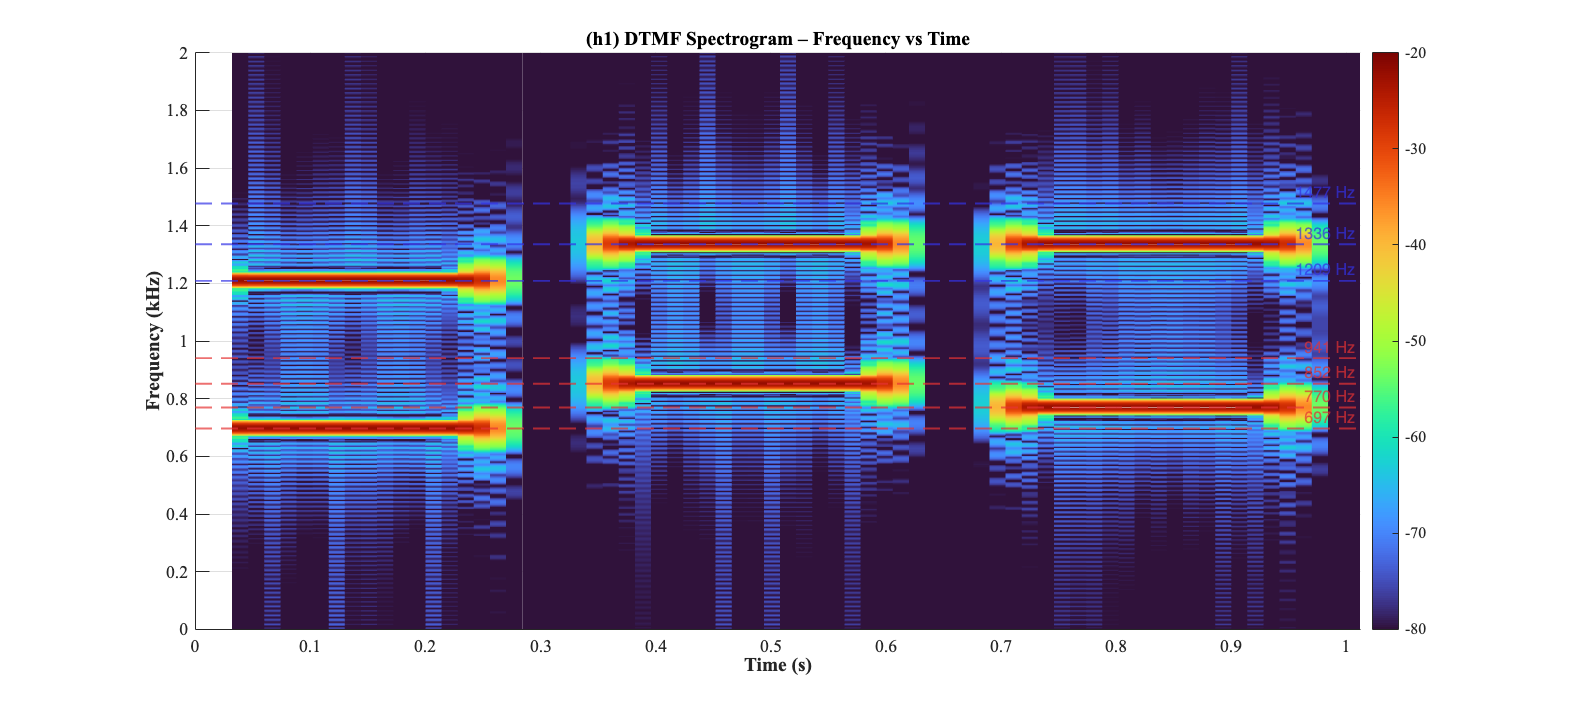

% Spectrogram 
window = 512; noverlap = 400; nfft = 2048;
[S,F,T,P] = spectrogram(x,window,noverlap,nfft,fs,'yaxis');
P_dB = 10*log10(abs(P)+eps);

figure('Position',[100,500,1000,450],'Color','w');
surf(T, F/1000, P_dB, 'EdgeColor','none');
axis tight; view(0,90);
colormap(turbo); colorbar;
caxis([-80 -20]);
xlabel('Time (s)','FontSize',12,'FontWeight','bold');
ylabel('Frequency (kHz)','FontSize',12,'FontWeight','bold');
title('(h1) DTMF Spectrogram – Frequency vs Time','FontSize',14,'FontWeight','bold');
ylim([0 2]); xlim([0 T(end)]);
set(gca,'FontSize',11);

hold on;
for i=1:length(low_freqs)
    yline(low_freqs(i)/1000,'--',sprintf('%d Hz',low_freqs(i)), ...
        'Color',[0.9 0.2 0.2],'LineWidth',1.2);
end
for i=1:length(high_freqs)
    yline(high_freqs(i)/1000,'--',sprintf('%d Hz',high_freqs(i)), ...
        'Color',[0.2 0.2 0.9],'LineWidth',1.2);
end
hold off;

frame_len = round(0.03 * fs); % 30ms
energy = x.^2;
energy_smooth = movmean(energy, frame_len);

% adaptive threshold
threshold = 0.04 * max(energy_smooth);
active = energy_smooth > threshold;

% detect start and end points
diff_active = diff([0; active; 0]);
starts = find(diff_active == 1);
ends = find(diff_active == -1) - 1;

% filter out too short regions
durations = (ends - starts)/fs;
valid = durations > 0.05; % at least 50 ms
starts = starts(valid); ends = ends(valid);
numTones = numel(starts);

fprintf('Detected %d tone segments.\n', numTones);

Detected 3 tone segments.


tolerance = 25; % Hz
decoded_sequence = {};

for i = 1:numTones
    segment = x(starts(i):ends(i));
    Nseg = length(segment);
    Nfft = 2^nextpow2(Nseg*4);
    Y = fft(segment .* hamming(Nseg), Nfft);
    f = (0:Nfft/2)*(fs/Nfft);
    mag = abs(Y(1:Nfft/2+1));

    [pks, locs] = findpeaks(mag, 'SortStr','descend','NPeaks',6, ...
        'MinPeakHeight',0.15*max(mag));

    if numel(locs) < 2, continue; end
    freqs = sort(f(locs(1:2)));

    low_f = min(freqs); high_f = max(freqs);
    [~, low_idx] = min(abs(low_f - low_freqs));
    [~, high_idx] = min(abs(high_f - high_freqs));
    low_det = low_freqs(low_idx);
    high_det = high_freqs(high_idx);

    if abs(low_f-low_det)<=tolerance && abs(high_f-high_det)<=tolerance
        key = dtmf_keys{low_idx,high_idx};
    else
        key = '?';
    end

    decoded_sequence{end+1} = key;
    fprintf('Tone %d: %.2f–%.2f s -> (%.1f Hz, %.1f Hz) → Key %s\n', ...
        i, starts(i)/fs, ends(i)/fs, low_f, high_f, key);
end

Tone 1: 0.00–0.26 s -> (696.8 Hz, 1209.0 Hz) → Key 1
Tone 2: 0.34–0.61 s -> (852.1 Hz, 1335.9 Hz) → Key 8
Tone 3: 0.69–0.96 s -> (770.0 Hz, 1335.9 Hz) → Key 5


fprintf('\nDecoded Sequence: %s\n', strjoin(decoded_sequence,' '));


Decoded Sequence: 1 8 5


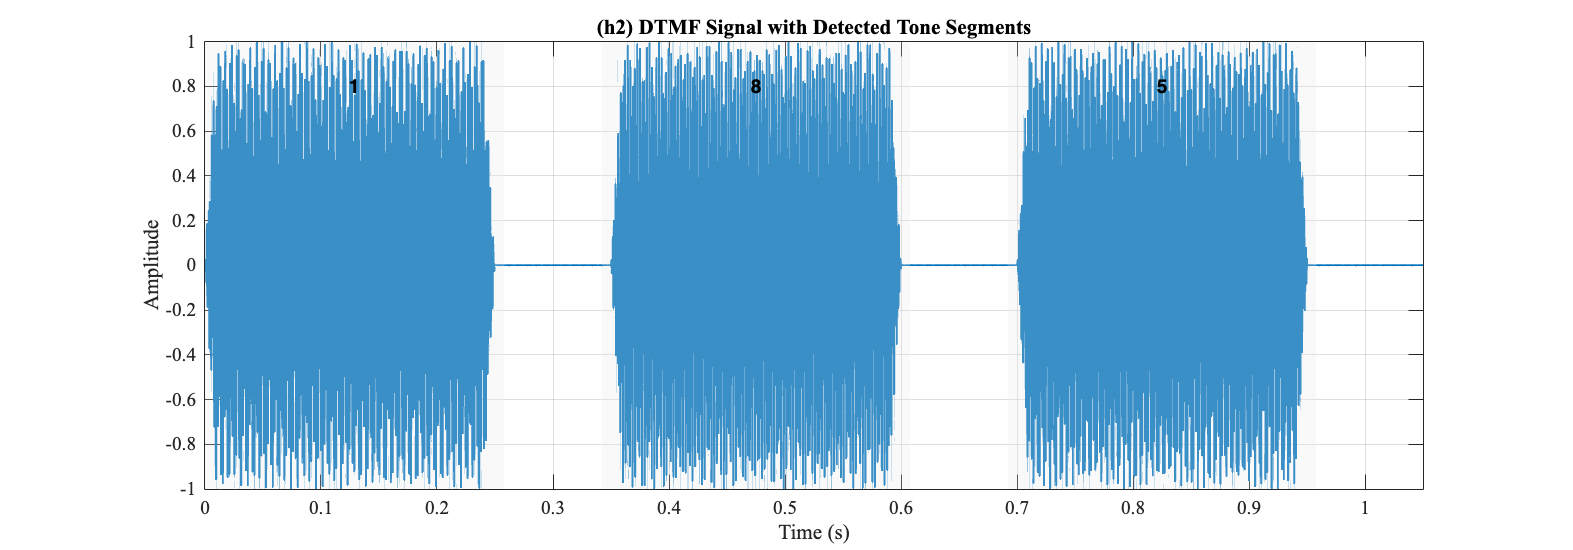

% Visualization of detected segments 
figure('Position',[150,150,1000,350],'Color','w');
plot(t, x, 'Color', [0 0.4470 0.7410], 'LineWidth', 1.3);
xlabel('Time (s)'); ylabel('Amplitude');
title('(h2) DTMF Signal with Detected Tone Segments','FontSize',14,'FontWeight','bold');
grid on; hold on;

for i = 1:numTones
    s_t = starts(i)/fs; e_t = ends(i)/fs;
    patch([s_t s_t e_t e_t], [ylim fliplr(ylim)], ...
        [0.9 0.9 0.9], 'FaceAlpha', 0.25, 'EdgeColor','none');
    % label key on top of each region
    text(mean([s_t e_t]), 0.8*max(x), decoded_sequence{i}, ...
        'HorizontalAlignment','center','FontSize',12,'FontWeight','bold');
end
xlim([0 t(end)]);
hold off;